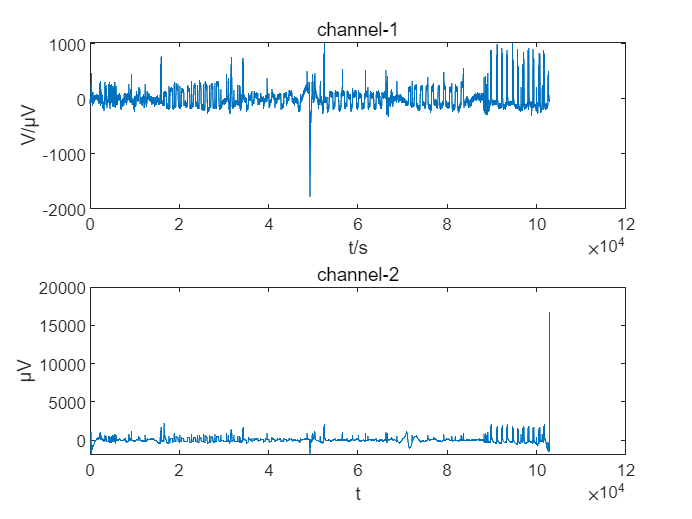

%waveletType = 'db4';   good
waveletType='dmey';
level = 11;  % 分解层数可以根据你的数据调整

data=emg_div(~any(isnan(emg_div), 2), :);
data_filtered = zeros(size(data));  % 初始化过滤后的数据矩阵

for k = 1:2
    [C, L] = wavedec(data(:,k), level, waveletType);  % 小波分解
    C(1:L(1)) = 0;  % 去除最低频的近似系数
    data_filtered(:,k) = waverec(C, L, waveletType);  % 重构信号
end

%% 小波滤波后图像
figure(1);
subplot(2,1,1)
plot(data_filtered(1:end,1));
xlabel('t/s');
ylabel('V/μV');
title('channel-1');

subplot(2,1,2)
plot(data_filtered(:,2));
xlabel('t');
ylabel('μV');
title('channel-2');